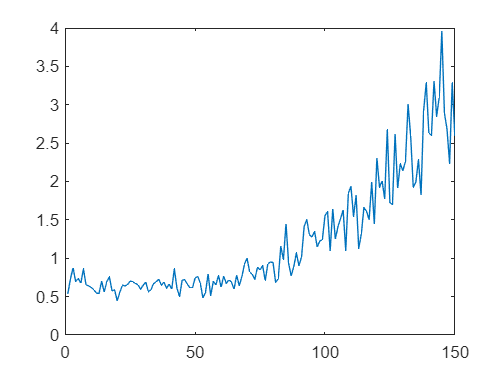

clear;
clc;


BlurTest = importdata("BlurTest.csv");
BlurTestBinary = importdata("BlurTest_binary.csv");
BlurTestAvg = zeros(1,150);
BlurTestElbow = zeros(1,150);
for i = 1:150
    BlurTestAvg(i) = mean(BlurTest(i,:));
end
plot(BlurTestAvg*100)

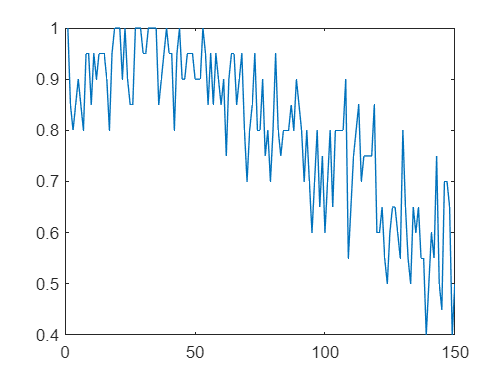

for i = 1:150
    BlurTestElbow(i) = sum(BlurTestBinary(i,:)) / 20;
end
plot(BlurTestElbow)

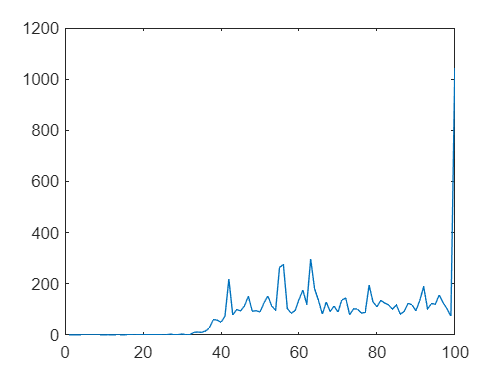




SPTest = importdata("SPTest.csv");
SPTestBinary = importdata("SPTest_binary.csv");
SPTestAvg = zeros(1,100);
SPTestElbow = zeros(1,100);
for i = 1:100
    SPTestAvg(i) = mean(SPTest(i,:));
end
plot(SPTestAvg*100)

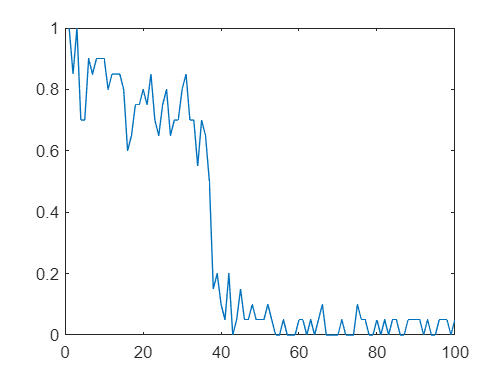

for i = 1:100
    SPTestElbow(i) = sum(SPTestBinary(i,:)) / 20;
end
plot(SPTestElbow)




BlurSPTest = importdata("BlurSPTest.csv");
BlurSPTestBinary = importdata("BlurSPTest_binary.csv");
BlurSPTestAvg = zeros(1,51);
BlurSPTestElbow = zeros(1,51);
for i = 1:51
    BlurSPTestAvg(i) = mean(BlurSPTest(i,:));
end

Index in position 1 exceeds array bounds. Index must not exceed 51.

plot(BlurSPTestAvg*100)
for i = 1:51
    BlurSPTestElbow(i) = sum(BlurSPTestBinary(i,:)) / 20;
end

plot(BlurSPTestElbow)







%boxplot([NoNoise*100, G_10*100, G_20*100, G_40*100, G_80*100, G_160*100, G_200*100])


